clearvars;

## Image Source Method

We are implementing a new version of the image source method (ISM), that only returns the pressure value at a specific point in time T.

T is chosen such, that the signal of all image sources has reached any point in the room.

L = [6,4,5]; % room dimensions.
alpha = [1,1,1,1,1,1];
A = [0 0 0; 0 0 0; L(1) 0 0; 0 L(2) 0; 0 0 0; 0 0 L(3)];
B = [0 1 0; 0 0 1; L(1) 1 0; 1 L(2) 0; 0 1 0; 1 0 L(3)];
C = [0 0 1; 1 0 0; L(1) 0 1; 0 L(2) 1; 1 0 0; 0 1 L(3)];
% Conversion of points into the plane quation coefficients of the walls
n_walls = size(A,1);
wall = zeros(n_walls,4);
for i=1:n_walls
   wall(i,:) = plane_equation(A(i,:),B(i,:),C(i,:)); 
end
h = waitbar(0,'Initializing waitbar...');
for order=1:5
    idx = 1;
    maxM = zeros(1,46656);
    for i1=0:L(1)
        for i2=0:L(2)
            for i3=0:L(3)
                for j1=0:L(1)
                    for j2=0:L(2)
                        for j3=0:L(3)
                            S = [i1,i2,i3]; R = [j1,j2,j3];
                            % Computation of the image points of S in relation to the walls/planes
                            % and its absorption coefficient.
                            M = S;
                            beta = ones(1,size(S,1));
                            for i=1:order
                                [M, beta] = point_mirror(wall,M,R,alpha,beta);
                            end
                            maxM(idx) = max(max(abs(M)));
                            idx = idx +1;
                        end
                    end
                end
            end
        end
    end
    waitbar(order/10,h,'Halfway there...')
    maxO(order) = max(maxM);
end

close(h);
maxO

This little test shows that the longest possible distance in a room of max(size) 5 is $(order+1)\cdot 5$

Therefore every image source wave will have reached the receiver before


$$T = \frac{(order+1)\cdot max(\mathbf L)}{c}$$


where

$order$ is the image source order,

$\mathbf L$ is the room dimension vector,

$c$ is the speed of sound.

We now change the previously implemented image source method to return only the pressure deviation at that time T.

We excecute the ims method now for a grid of measurement points.

clearvars;
beta = 1; n = 500;
L = [n,n,n]; spacing = 0.01;
f = 800; c = 343; omega = 2*pi*f;
S = [n/2,n/2,n/2];
alpha = [0.5,0.9,0.5,0.9,0.5,0.5];
order = 1;
T = (order+1)*max(L)*spacing/c;
out_p_abs = zeros(1,n-1);
 
for x=1:n-1
    for y=1:n-1
        p(x,y) = ISM2(S,[x,y,n/2],L,omega,c,alpha,T,order,spacing);
    end
end

colorScale = mean(mean(imag(p(abs(p) ~= inf))))

colorScale = -0.0010

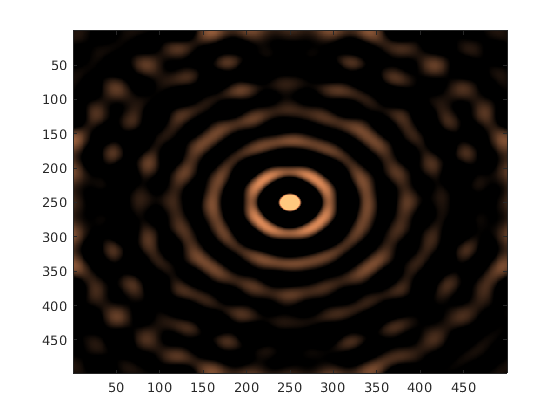

image(imag(p)/colorScale); colormap copper;